clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = ".png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "./tex/images/";
mkdir(SAVE_DIR);

a_1 = 2;
a_0 = -3;
b_0 = 2;

k_M_1 = 5;
k_M_0 = 6;

b_M_0 = 1;

Lambda = -b_0;
mu_1 = 1;
mu_2 = 2;
mu_3 = 3;
gamma_0 = diag([1 1 1 0.01]) * 10000;

ss_obj = ss(tf([b_0], [1, a_1, a_0]));
if rank(ctrb(ss_obj)) == 2
    disp('Controllable, U =');
    disp(ctrb(ss_obj))
end

Controllable, U =


     1    -2
     0     2



if rank(obsv(ss_obj)) == 2
    disp('Observable, V =');
    disp(obsv(ss_obj))
end

Observable, V =


     0     1
     2     0



disp('Poles: ');

Poles: 


disp(pole(ss_obj));

   -3.0000
    1.0000



Лаба 8

gammas = [1, 5, 40];
gamma = gammas(1);
out1_1 = sim("lab8.slx", 1000);
gamma = gammas(2);
out1_2 = sim("lab8.slx", 1000);
gamma = gammas(3);
out1_3 = sim("lab8.slx", 1000);

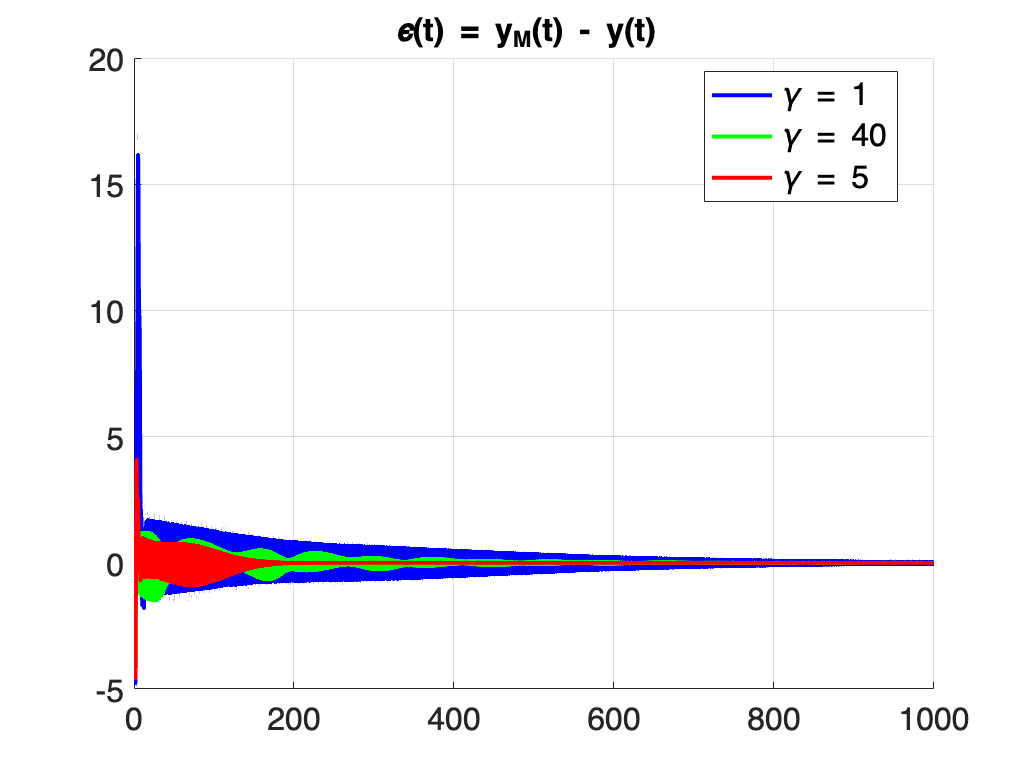

clf;
hold on
grid on;
title("\epsilon(t) = y_M(t) - y(t) ");
plot(out1_1.y.time, out1_1.y.data - out1_1.y_m.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
plot(out1_3.y.time, out1_3.y.data - out1_3.y_m.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
plot(out1_2.y.time, out1_2.y.data - out1_2.y_m.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
legend({'\gamma = 1', '\gamma = 40', '\gamma = 5'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task1_eps" + SAVE_EXT);
hold off

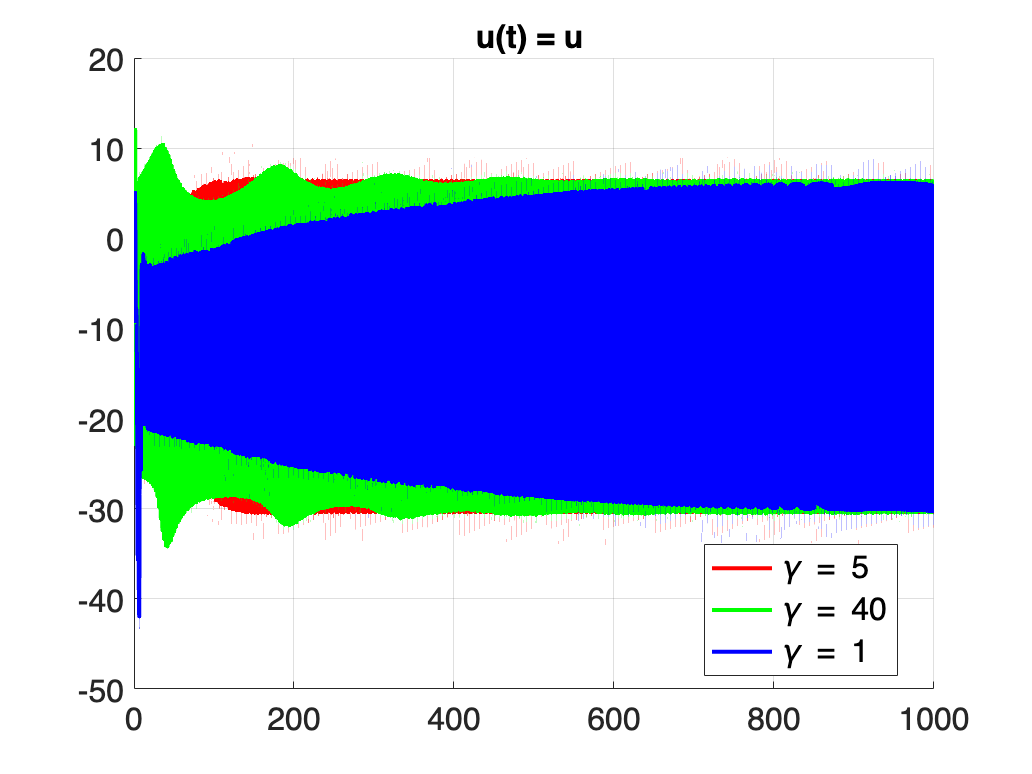

clf;
hold on
grid on;
title("u(t) = u ");
plot(out1_2.y.time, out1_2.u.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
plot(out1_3.y.time, out1_3.u.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
plot(out1_1.y.time, out1_1.u.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
legend({'\gamma = 5', '\gamma = 40', '\gamma = 1'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task1_u" + SAVE_EXT);
hold off

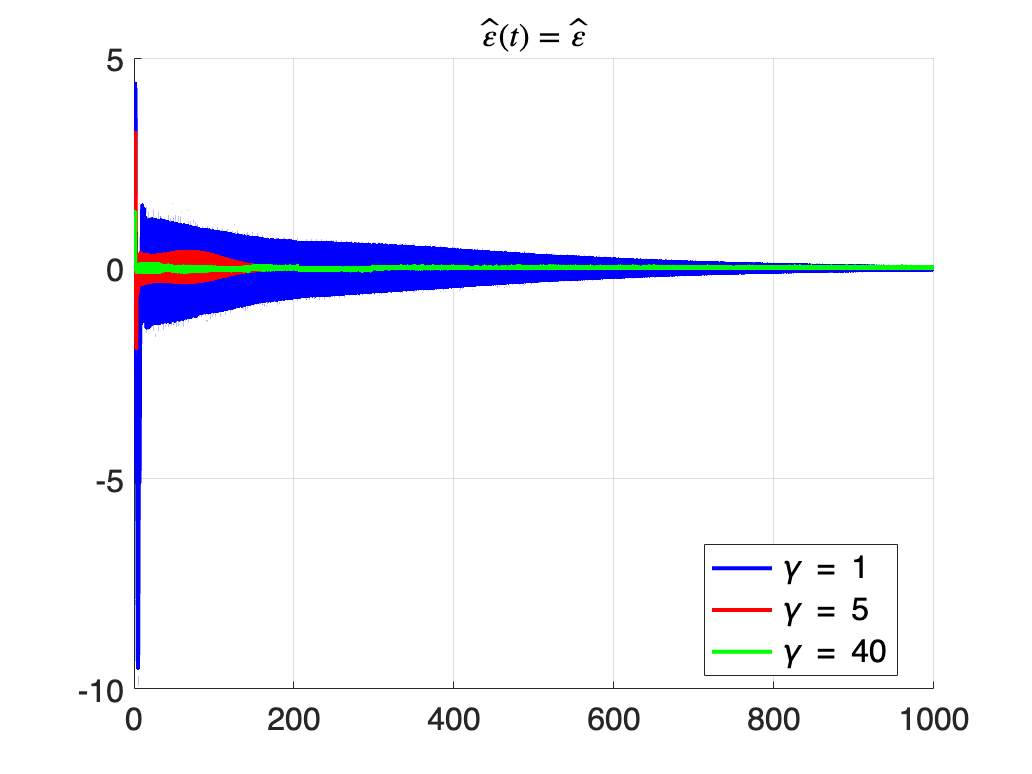

clf;
hold on
grid on;
title("$$\hat \varepsilon (t) = \hat \varepsilon$$", 'Interpreter','latex');
plot(out1_1.y.time, out1_1.err_hat.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
plot(out1_2.y.time, out1_2.err_hat.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
plot(out1_3.y.time, out1_3.err_hat.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
legend({'\gamma = 1', '\gamma = 5', '\gamma = 40'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task1_eps_hat" + SAVE_EXT);
hold off

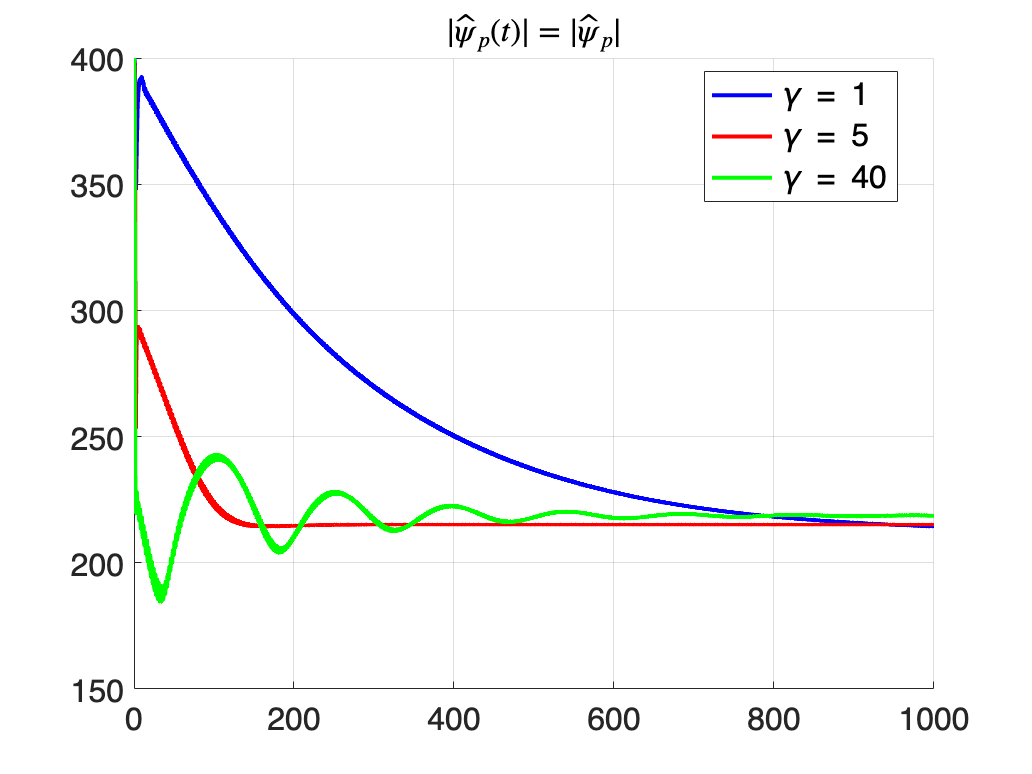

clf;
hold on
grid on;
title("$$|\hat \psi_p (t)| = |\hat \psi_p| $$", 'Interpreter','latex');
plot(out1_1.y.time, out1_1.psi_p_norm.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
plot(out1_2.y.time, out1_2.psi_p_norm.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
plot(out1_3.y.time, out1_3.psi_p_norm.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
legend({'\gamma = 1', '\gamma = 5', '\gamma = 40'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task1_psi_p_hat" + SAVE_EXT);
hold off

Лаба 8 + модификация

gamma_0 = diag([1 1 1 0.01]) * gammas(1)*10;
out2_1 = sim("lab8_modified.slx", 100);
gamma_0 = diag([1 1 1 0.01]) * gammas(2)*100;
out2_2 = sim("lab8_modified.slx", 100);
gamma_0 = diag([1 1 1 0.01]) * gammas(3)*300;
out2_3 = sim("lab8_modified.slx", 100);

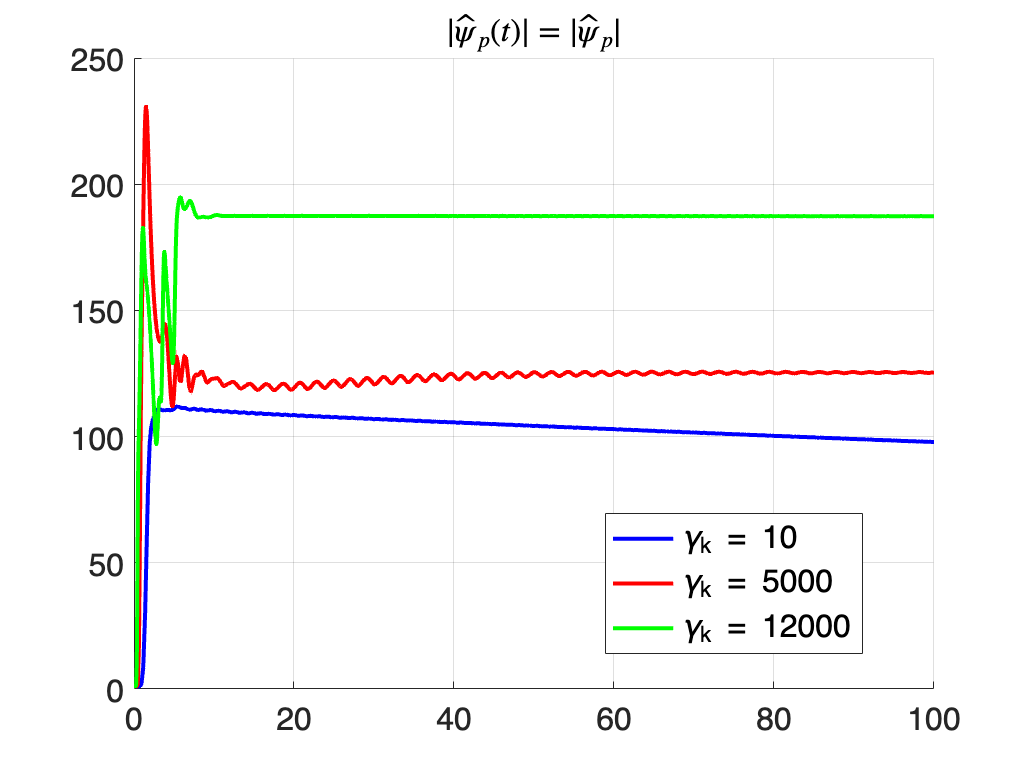

clf;
hold on
grid on;
title("$$|\hat \psi_p (t)| = |\hat \psi_p| $$", 'Interpreter','latex');
plot(out2_1.y.time, out2_1.psi_p_norm.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
plot(out2_2.y.time, out2_2.psi_p_norm.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
plot(out2_3.y.time, out2_3.psi_p_norm.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
legend({'\gamma_k = 10', '\gamma_k = 5000', '\gamma_k = 12000'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task2_psi_p_hat" + SAVE_EXT);
hold off

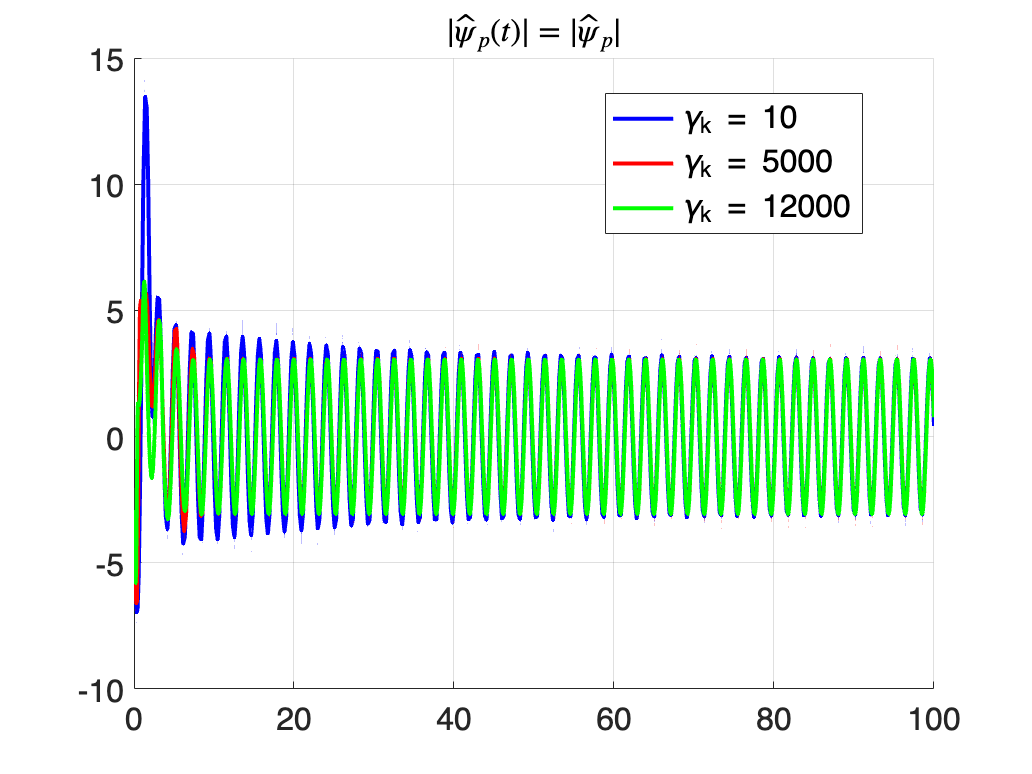

clf;
hold on
grid on;
title("$$|\hat \psi_p (t)| = |\hat \psi_p| $$", 'Interpreter','latex');
plot(out2_1.y.time, out2_1.u.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
plot(out2_2.y.time, out2_2.u.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
plot(out2_3.y.time, out2_3.u.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
legend({'\gamma_k = 10', '\gamma_k = 5000', '\gamma_k = 12000'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task2_u" + SAVE_EXT);
hold off

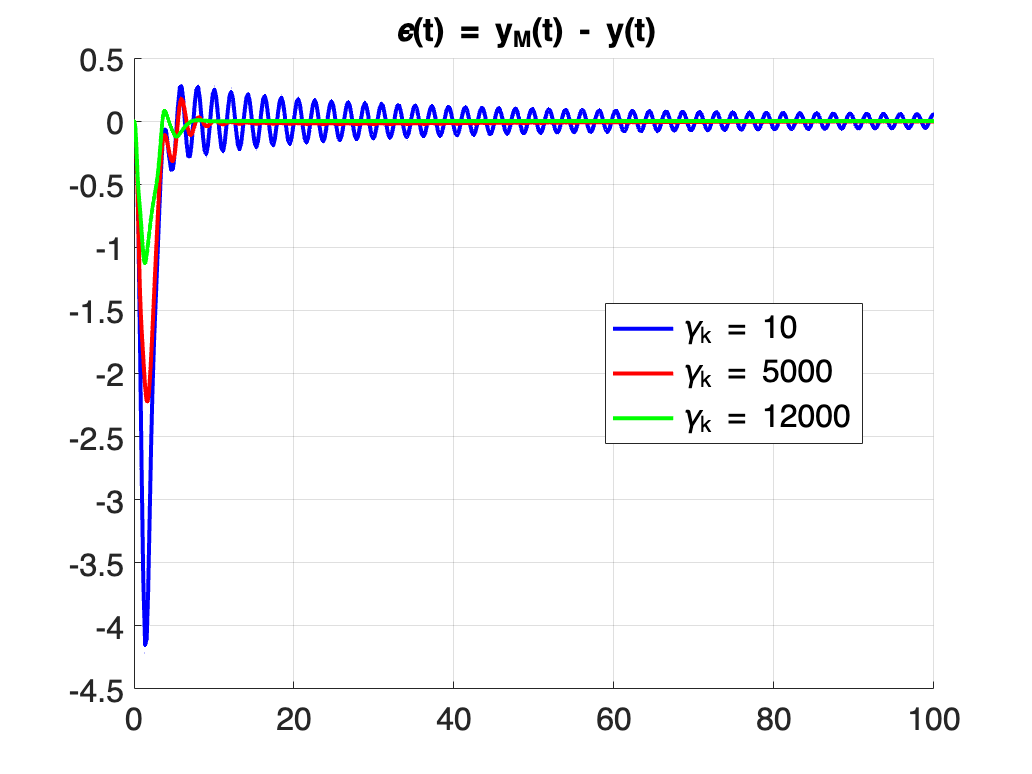

clf;
hold on
grid on;
title("\epsilon(t) = y_M(t) - y(t) ");
plot(out2_1.y.time, out2_1.y.data - out2_1.y_m.data, 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
plot(out2_2.y.time, out2_2.y.data - out2_2.y_m.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
plot(out2_3.y.time, out2_3.y.data - out2_3.y_m.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
legend({'\gamma_k = 10', '\gamma_k = 5000', '\gamma_k = 12000'}, 'Location', 'best');
fontsize(16, "points");
exportgraphics(gcf, SAVE_DIR + "task2_eps" + SAVE_EXT);
hold off